# AM4 Data Analysis Dashboard

if exist('AM4_Data')
else
    load('AM4_Data.mat')
end

### Run Selection:

Choose which AM4 runs you'd like to plot

%% 4. EGR Plotting
% Select which runs you want plotted    
Run_choice_1=true;
Run_choice_2=false; Run_choice_3=false;
Run_choice_10=true; Run_choice_11=true;
Run_choice_4=false; Run_choice_5=false; Run_choice_6=false;
Run_choice_9=false; Run_choice_8=false; Run_choice_7=false;

plot_choices = [1 2 3 4 5 6 7 8 9 10 11];
plot_choices = plot_choices([Run_choice_1 Run_choice_2 Run_choice_3 Run_choice_4 Run_choice_5 Run_choice_6 Run_choice_7 Run_choice_8 Run_choice_9 Run_choice_10 Run_choice_11]);

#### Select the Latitude Range: 

Select either a custom range ***or*** a pre-selected range

if  false;
    Min_Lat_Range = -90;
    Max_Lat_Range = -60;
    AM4_Data.lat_range_names{7} = "Custom"; AM4_Data.lat_range{7} = find(AM4_Data.lat<Max_Pressure_Range & AM4_Data.lat>Min_Pressure_Range);
    Lat_Band_Choice = 7;
else true;
    Lat_Band_Choice = 6;
end
AM4_Data.p_range_names{4} = "Custom"; AM4_Data.p_range{4} = find(AM4_Data.p<Max_Pressure_Range & AM4_Data.p>Min_Pressure_Range);

## Eady Growth Rate Plotted over the first 100 days:

Eady Growth Rate is calculated as: $\left|\frac{f_0 }{N}\frac{\partial u}{\partial z}\right|$, with $N^2 =\frac{g}{\theta }\frac{\partial \theta }{\partial z}$. 

The moist Eady Growth Rate is calculated using an *effective* static stability: ${\frac{\partial \theta }{\partial z}}_{\mathrm{eff}} =\frac{\partial \theta }{\partial z}-\lambda \frac{\partial \theta }{\partial z}|_{\theta^* }$

#### Basic:

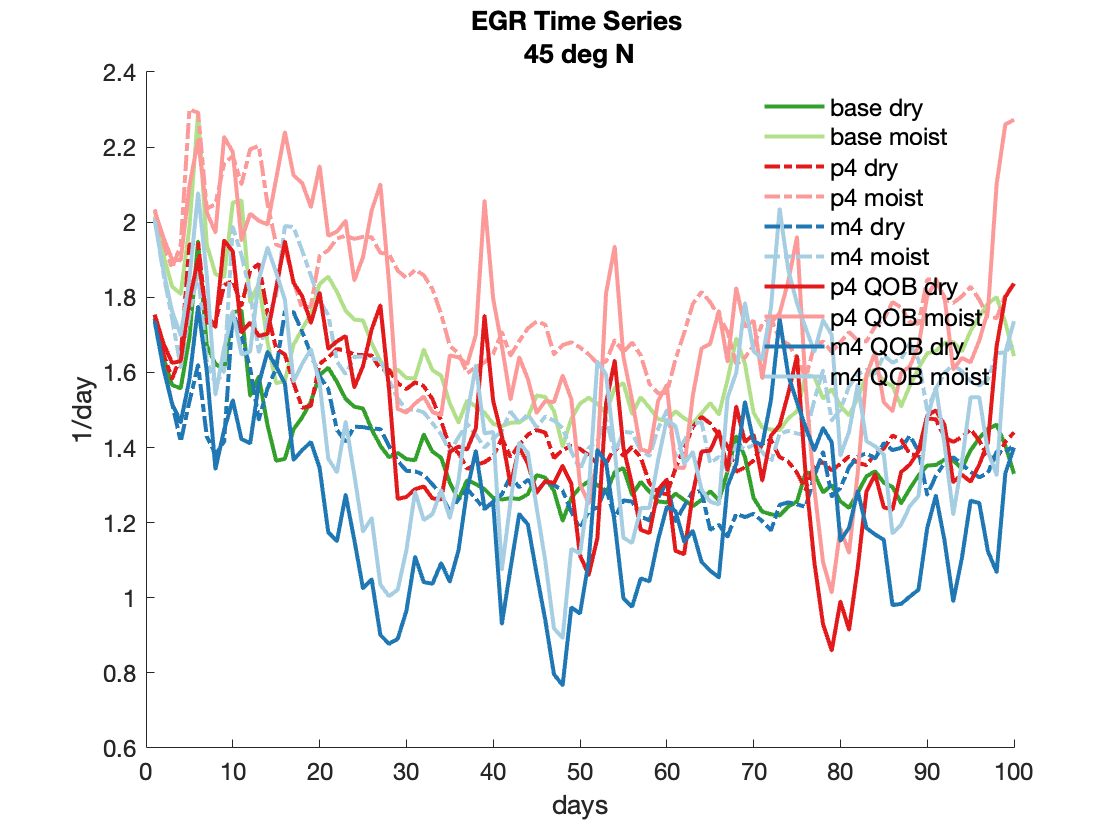

if true   
%Time Series
    for lat_band = Lat_Band_Choice  
        EGR_TimeSeries = figure(1); clf; hold on; plot_count = 1; legend_names = [];
        for plot_num = plot_choices
            temp_plots(plot_count) = plot(1:100, squeeze( nanmean( AM4_Data.dry_egr{plot_num}(:,AM4_Data.lat_range{lat_band},:,:), [1 2 3] ) ) *86400 ,'LineWidth',2, 'Color',AM4_Data.Color{plot_num}(2,:), 'LineStyle', AM4_Data.Line_Style{plot_num} ); legend_names{plot_count} = [AM4_Data.codename{plot_num} ' dry']; plot_count = plot_count +1;
            temp_plots(plot_count) = plot(1:100, squeeze( nanmean( AM4_Data.moist_egr{plot_num}(:,AM4_Data.lat_range{lat_band},:,:), [1 2 3] ) ) *86400 ,'LineWidth',2, 'Color',AM4_Data.Color{plot_num}(1,:), 'LineStyle', AM4_Data.Line_Style{plot_num} ); legend_names{plot_count} = [AM4_Data.codename{plot_num} ' moist']; plot_count = plot_count +1;
        end
        ylabel("1/day"); xlabel("days"); legend(legend_names,'FontSize',12); legend('boxoff'); set(gca,'FontSize',12)
        title(["EGR Time Series ", AM4_Data.lat_range_names{lat_band}])
        saveas(EGR_TimeSeries,[strcat('./plots/Master/EGR/Time_Series/Time_Series',AM4_Data.lat_range_names{lat_band},'.png')])
    end
end

#### Difference - as 1/days and as a % of dry EGR

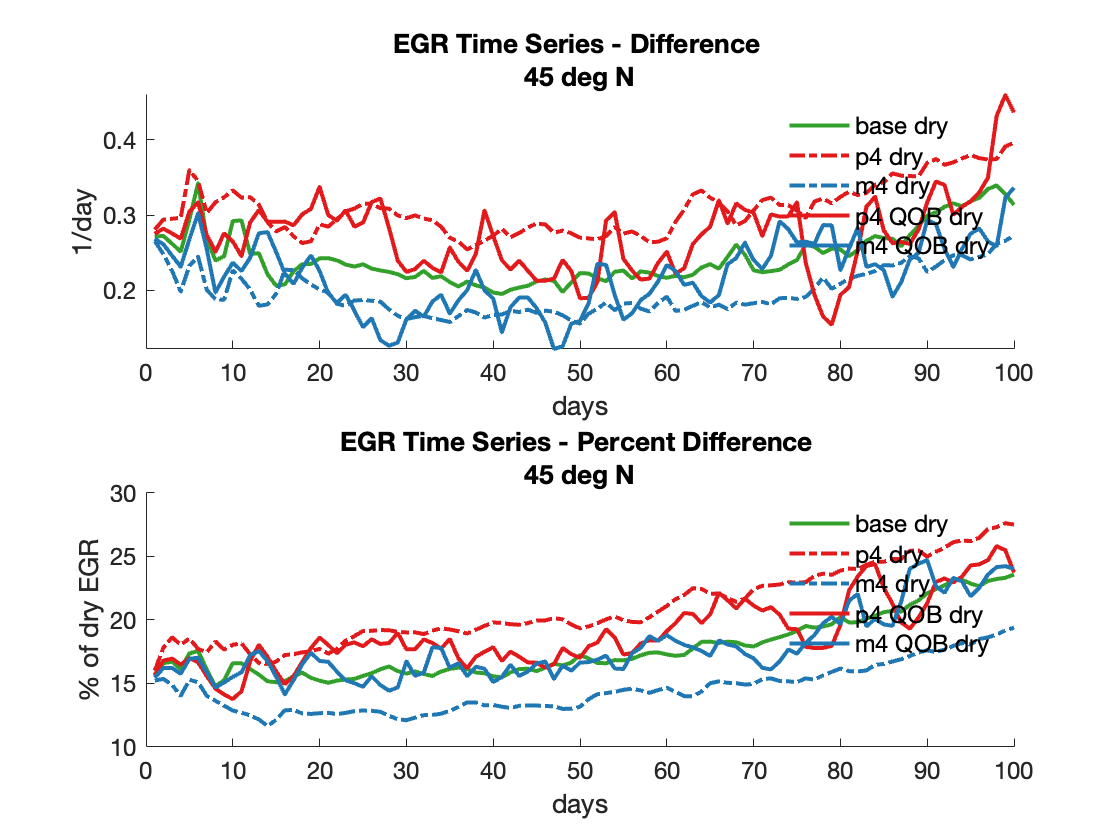

if true   
%% Time Series - difference
    for lat_band = Lat_Band_Choice    
        EGR_TimeSeries_diff = figure(2); clf;subplot(2,1,1); hold on; plot_count = 1; legend_names = [];

        for plot_num = plot_choices
            temp_plots(plot_count) = plot(1:100, (squeeze( nanmean( AM4_Data.moist_egr{plot_num}(:,AM4_Data.lat_range{lat_band},:,:), [1 2 3] ) ) - squeeze( nanmean( AM4_Data.dry_egr{plot_num}(:,AM4_Data.lat_range{lat_band},:,:), [1 2 3] ) ) ) *86400 ,'LineWidth',2, 'Color',AM4_Data.Color{plot_num}(2,:), 'LineStyle', AM4_Data.Line_Style{plot_num} ); legend_names{plot_count} = [AM4_Data.codename{plot_num} ' dry']; plot_count = plot_count +1;
        end
        ylabel("1/day"); xlabel("days"); legend(legend_names,'FontSize',12); legend('boxoff'); axis([0 100 -inf inf]); set(gca,'FontSize',12)
        title(["EGR Time Series - Difference ", AM4_Data.lat_range_names{lat_band}])
        
        subplot(2,1,2); hold on; plot_count = 1; legend_names = [];
        for plot_num = plot_choices
            temp_plots(plot_count) = plot(1:100, (squeeze( nanmean( AM4_Data.moist_egr{plot_num}(:,AM4_Data.lat_range{lat_band},:,:), [1 2 3] ) ) - squeeze( nanmean( AM4_Data.dry_egr{plot_num}(:,AM4_Data.lat_range{lat_band},:,:), [1 2 3] ) ) ) ./ squeeze( nanmean( AM4_Data.dry_egr{plot_num}(:,AM4_Data.lat_range{lat_band},:,:), [1 2 3] ) ) *100  ,'LineWidth',2, 'Color',AM4_Data.Color{plot_num}(2,:), 'LineStyle', AM4_Data.Line_Style{plot_num} ); legend_names{plot_count} = [AM4_Data.codename{plot_num} ' dry']; plot_count = plot_count +1;
        end
        ylabel("% of dry EGR"); xlabel("days"); legend(legend_names,'FontSize',12); legend('boxoff'); axis([0 100 10 30]);set(gca,'FontSize',12)
        title(["EGR Time Series - Percent Difference ", AM4_Data.lat_range_names{lat_band}])
        saveas(EGR_TimeSeries_diff,[strcat('./plots/Master/EGR/Time_Series/Time_Series_Diff_',AM4_Data.lat_range_names{lat_band},'.png')])
    end
end

## Eady Growth Rate Plotted as a function of latitude:

#### Basic:

if false      
%%
   %Latitude Series
    for lat_band = Lat_Band_Choice    
        EGR_LatSeries = figure(3); clf; hold on; plot_count = 1; legend_names = [];
        for plot_num = plot_choices
            temp_plots(plot_count) = plot(AM4_Data.lat, squeeze( nanmean( AM4_Data.dry_egr{plot_num}(:,:,:,:), [1 3 4] ) ) *86400 ,'LineWidth',2, 'Color',AM4_Data.Color{plot_num}(2,:), 'LineStyle', AM4_Data.Line_Style{plot_num} ); legend_names{plot_count} = [AM4_Data.codename{plot_num} ' dry']; plot_count = plot_count +1;
            temp_plots(plot_count) = plot(AM4_Data.lat, squeeze( nanmean( AM4_Data.moist_egr{plot_num}(:,:,:,:), [1 3 4] ) ) *86400 ,'LineWidth',2, 'Color',AM4_Data.Color{plot_num}(1,:), 'LineStyle', AM4_Data.Line_Style{plot_num} ); legend_names{plot_count} = [AM4_Data.codename{plot_num} ' moist']; plot_count = plot_count +1;
        end
        ylabel("1/day"); xlabel("latitutde"); legend(legend_names,'FontSize',12); legend('boxoff'); set(gca,'FontSize',12)
        title(["EGR Lat Series - days 1:100"])
        saveas(EGR_LatSeries,[strcat('./plots/Master/EGR/Lat_Series/Lat_Series',AM4_Data.lat_range_names{lat_band},'.png')])
    end
end

#### **Difference - as 1/days and as a % of dry EGR:**

if false   
    %Latitude Series - difference
    for lat_band = Lat_Band_Choice    
        EGR_LatSeries_diff = figure(4); clf;subplot(2,1,1); hold on; plot_count = 1; legend_names = [];

        for plot_num = plot_choices
            temp_plots(plot_count) = plot(AM4_Data.lat, (squeeze( nanmean( AM4_Data.moist_egr{plot_num}(:,:,:,:), [1 3 4] ) ) - squeeze( nanmean( AM4_Data.dry_egr{plot_num}(:,:,:,:), [1 3 4] ) )) *86400 ,'LineWidth',2, 'Color',AM4_Data.Color{plot_num}(2,:), 'LineStyle', AM4_Data.Line_Style{plot_num} ); legend_names{plot_count} = [AM4_Data.codename{plot_num} ' dry']; plot_count = plot_count +1;
        end
        ylabel("1/day"); xlabel("latitutde"); legend(legend_names,'FontSize',12); legend('boxoff'); axis([-90 90 -inf inf]); set(gca,'FontSize',12)
        title(["EGR Lat Series - Difference ", AM4_Data.lat_range_names{lat_band}])
        
        subplot(2,1,2); hold on; plot_count = 1; legend_names = [];
        for plot_num = plot_choices
            temp_plots(plot_count) = plot(AM4_Data.lat, (squeeze( nanmean( AM4_Data.moist_egr{plot_num}(:,:,:,:), [1 3 4] ) ) - squeeze( nanmean( AM4_Data.dry_egr{plot_num}(:,:,:,:), [1 3 4] ) )) ./ squeeze( nanmean( AM4_Data.dry_egr{plot_num}(:,:,:,:), [1 3 4] ) )*100  ,'LineWidth',2, 'Color',AM4_Data.Color{plot_num}(2,:), 'LineStyle', AM4_Data.Line_Style{plot_num} ); legend_names{plot_count} = [AM4_Data.codename{plot_num} ' dry']; plot_count = plot_count +1;
        end
        ylabel("% of dry EGR"); xlabel("latitutde"); legend(legend_names,'FontSize',12); legend('boxoff'); axis([-90 90 0 70]);set(gca,'FontSize',12)
        title(["EGR Lat Series - Percent Difference ", AM4_Data.lat_range_names{lat_band}])
        saveas(EGR_LatSeries_diff,[strcat('./plots/Master/EGR/Lat_Series/Lat_Series_Diff_',AM4_Data.lat_range_names{lat_band},'.png')])
    end
end

## $N^2$ Plotted as a function of latitude and Pressure:


$$N^2 =\frac{g}{\theta }\frac{\partial \theta }{\partial z}$$


#### O'Gorman Fig. 4 recreation:

if false
for plot_num = plot_choices
    Ogorman_Tri_Plot = figure(100+plot_num); clf; subplot(3,1,1); hold on; plot_count = 1; legend_names = [];
    dryN2_temp = squeeze(nanmean(AM4_Data.dry_N2{plot_num}(:,:,:,:),[1,4]))'.*10^5;
    moistN2_temp = squeeze(nanmean(AM4_Data.moist_N2{plot_num}(:,:,1:12,:),[1,4]))'.*10^5;
    limits = [-80 80 50 925]; lines = [5 10 15 20 25 30]; minor_lines = [.2 .3 .4 .5 .6 .7 .8 .9];
    
    subplot(3,1,1)
    [M,c] = contour(AM4_Data.lat,AM4_Data.p, dryN2_temp,lines,'ShowText','on');
    ylabel('pressure'), title(strcat("N^2 dry * 10^5 - ", AM4_Data.codename{plot_num})), c.LineWidth = 2;
    axis(limits), set(gca, 'YDir','reverse')

    subplot(3,1,2)
    [M,c] = contour(AM4_Data.lat,AM4_Data.p, moistN2_temp,lines,'ShowText','on');
    ylabel('pressure'), title(strcat("N^2 dry * 10^5 - ", AM4_Data.codename{plot_num})), c.LineWidth = 2;
    axis(limits), set(gca, 'YDir','reverse')

    subplot(3,1,3)
    [M,c] = contour(AM4_Data.lat,AM4_Data.p, moistN2_temp./dryN2_temp,minor_lines,'ShowText','on');
    xlabel('latitude'), ylabel('pressure'), title('moist/dry'), c.LineWidth = 2; 
    axis(limits); set(gca, 'YDir','reverse')
    
    saveas(Ogorman_Tri_Plot,[strcat('./plots/Master/Strat/Ogorman_Fig_4/Triplot_',AM4_Data.codename{plot_num},'.png')])
end
end

#### N^2 Replotted recreation:

A moist/dry N^2 ratio below 1 means the static stability is decreased when moisture is taken into the calculation. As the ratio value decreases, moisture is having more of a 'destabilizing' effect. As moisture increases (in hotter runs), you can see a greater difference between the moist and dry static stability values. 

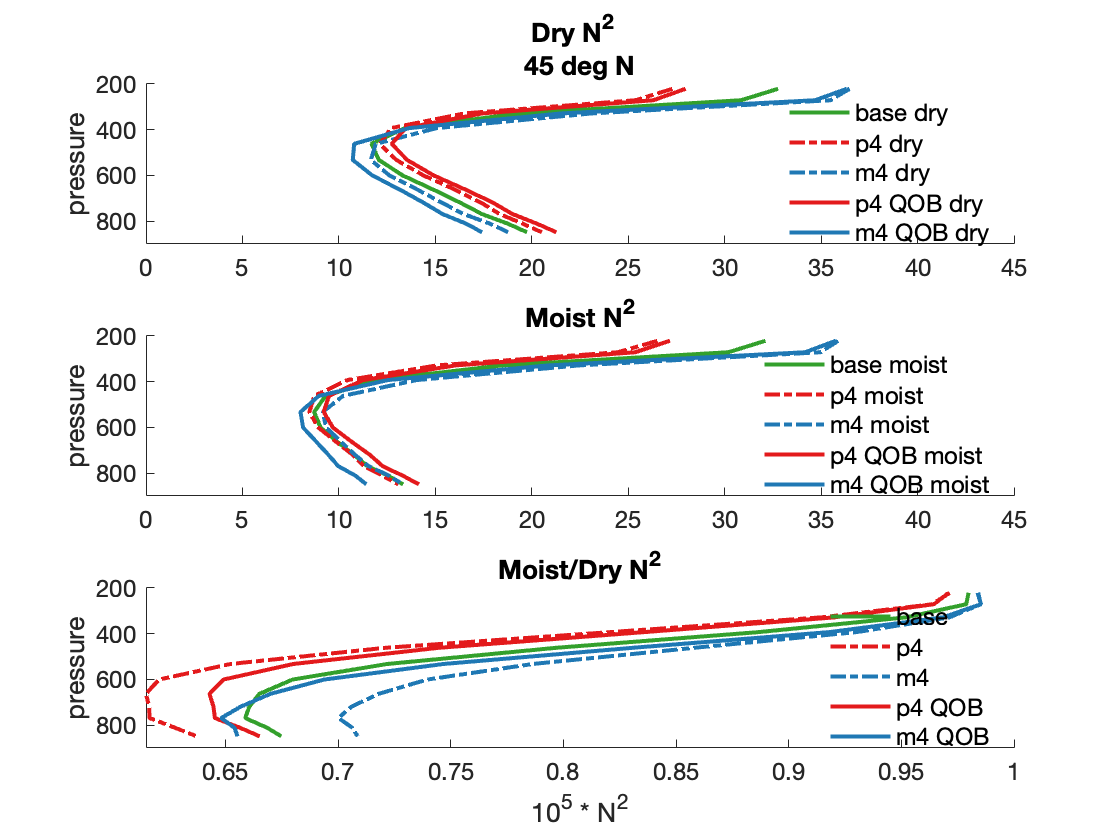

if true  
N2_Comparison = figure(110); clf; subplot(3,1,1), hold on; plot_count = 1; legend_names = [];
    for plot_num = plot_choices
        temp_plots(plot_count) = plot(squeeze( nanmean( AM4_Data.dry_N2{plot_num}(:,AM4_Data.lat_range{lat_band},:,:), [1 2 4] ) ) .*10^5, AM4_Data.p ,'LineWidth',2, 'Color',AM4_Data.Color{plot_num}(2,:), 'LineStyle', AM4_Data.Line_Style{plot_num} ); legend_names{plot_count} = [AM4_Data.codename{plot_num} ' dry']; plot_count = plot_count +1;
    end
        ylabel('pressure'); legend(legend_names,'FontSize',12); legend('boxoff'); set(gca,'FontSize',12)
        title(["Dry N^2  ", AM4_Data.lat_range_names{lat_band}]), set(gca, 'YDir','reverse'), axis([0 45 200 900])
    subplot(3,1,2); hold on; plot_count = 1; legend_names = [];
    for plot_num = plot_choices
        temp_plots(plot_count) = plot(squeeze( nanmean( AM4_Data.moist_N2{plot_num}(:,AM4_Data.lat_range{lat_band},:,:), [1 2 4] ) ) .*10^5, AM4_Data.p ,'LineWidth',2, 'Color',AM4_Data.Color{plot_num}(2,:), 'LineStyle', AM4_Data.Line_Style{plot_num} ); legend_names{plot_count} = [AM4_Data.codename{plot_num} ' moist']; plot_count = plot_count +1;
    end 
        title("Moist N^2"); ylabel('pressure'); legend(legend_names,'FontSize',12); legend('boxoff'); set(gca,'FontSize',12), set(gca, 'YDir','reverse'), axis([0 45 200 900])
    subplot(3,1,3); hold on; plot_count = 1; legend_names = [];
    for plot_num = plot_choices
        temp_plots(plot_count) = plot((squeeze( nanmean( AM4_Data.moist_N2{plot_num}(:,AM4_Data.lat_range{lat_band},:,:), [1 2 4] ) ) .*10^5)./(squeeze( nanmean( AM4_Data.dry_N2{plot_num}(:,AM4_Data.lat_range{lat_band},:,:), [1 2 4] ) ) .*10^5), AM4_Data.p ,'LineWidth',2, 'Color',AM4_Data.Color{plot_num}(2,:), 'LineStyle', AM4_Data.Line_Style{plot_num} ); legend_names{plot_count} = [AM4_Data.codename{plot_num}]; plot_count = plot_count +1;
    end 
        ylabel('pressure'); xlabel("10^5 * N^2"); legend(legend_names,'FontSize',12); legend('boxoff'); set(gca,'FontSize',12),set(gca, 'YDir','reverse'), axis([-inf 1 200 900]), title("Moist/Dry N^2")
end